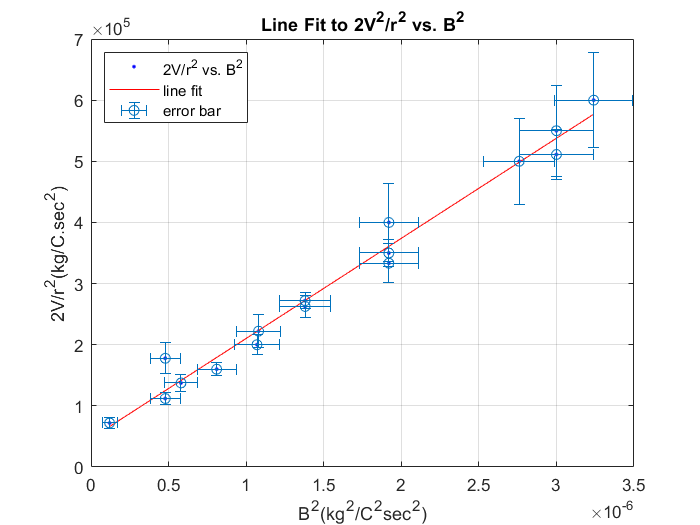

[xData, yData] = prepareCurveData( B2, C );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
% Label axes
xlabel B2
ylabel C
grid on
hold on

ypos=(sigmaC);
yneg=ypos;
xpos=(sigmaB2);
xneg=xpos;
errorbar(B2,C,yneg,ypos,xneg,xpos,'o');

legend({'2V/r^2 vs. B^2','line fit','error bar'},'Location','northwest');

xlabel('B^2(kg^2/C^2sec^2)')
ylabel('2V/r^2(kg/C.sec^2)')

title('Line Fit to 2V^2/r^2 vs. B^2')


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =   1.637e+11  (1.508e+11, 1.766e+11)
  %     p2 =   4.654e+04  (2.265e+04, 7.043e+04)

%Goodness of fit:
 % SSE: 7.745e+09
  %R-square: 0.9814
 % Adjusted R-square: 0.9801
  %RMSE: 2.352e+04